# Transducer Design

Transducer 1

% Define common properties
transducer_info = struct();
transducer_info.Frequency = 40000;        % 40kHz (operating frequency of transducer)
% transducer_info.Pressure = 36.3477;   % Surface outcome pressure [Pa]
transducer_info.Pressure = 1;  
transducer_info.Type = 'circle';
transducer_info.Radius = 5e-3;      
transducer_info.medium = 'air';

% Positions and phases for the transducers (1 row)
positions = [];
for k = 1:8
    positions(k) = 0.005 + 0.01 * (k-1);
end

% PFC_PhaseCalculate_for16(target[x,y], array, focal point z(m))
% phases = PFC_PhaseCalculate_for16([0.04, 0.04], [8,8], 0.2)
% phases = PFC_PhaseCalculate([0.04, 0.12], [8,8], 0.1)

phases =          0    5.3227   10.3949   15.1788   19.6312   23.7038   27.3441   30.4966
    1.4270    6.8195   11.9650   16.8249   21.3550   25.5056   29.2218   32.4454
    2.3884    7.8290   13.0251   17.9378   22.5220   26.7270   30.4966   33.7705
    2.8721    8.3373   13.5593   18.4990   23.1110   27.3441   31.1412   34.4411
    2.8721    8.3373   13.5593   18.4990   23.1110   27.3441   31.1412   34.4411
    2.3884    7.8290   13.0251   17.9378   22.5220   26.7270   30.4966   33.7705
    1.4270    6.8195   11.9650   16.8249   21.3550   25.5056   29.2218   32.4454
         0    5.3227   10.3949   15.1788   19.6312   23.7038   27.3441   30.4966


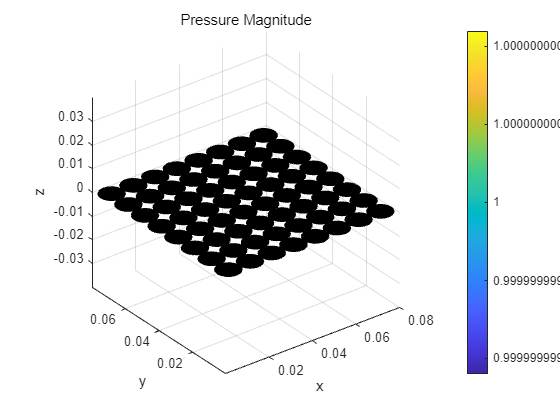

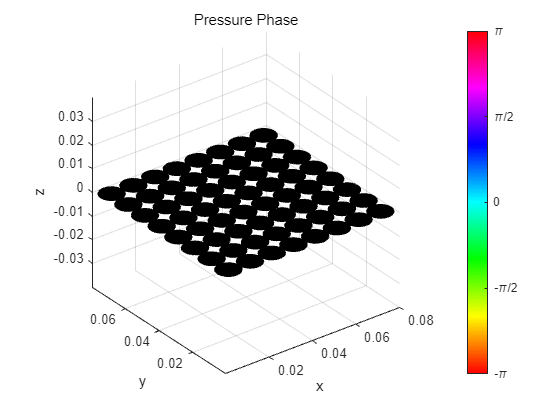

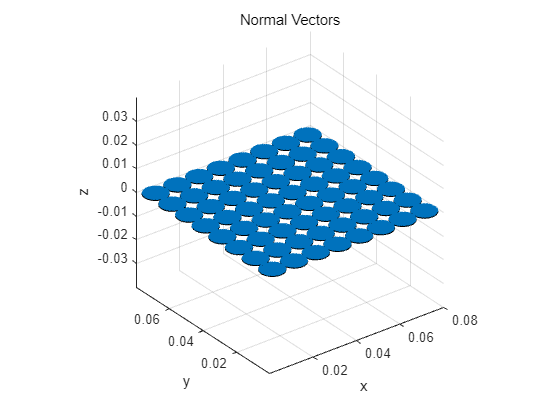


% Counter for linear indexing into transducer_object
index = 1;

% Populate the transducer objects
for i = 1:8
    for j = 1:8
        % Update position and phase
        transducer_info.position = [positions(j), positions(i), 0];

        % transducer_info.Phase = phases(i,j);
        transducer_info.Phase = phases(i,j);
        transducer_object(index) = PFC_Make3DTransducer(transducer_info);

        % Increment index for next transducer
        index = index + 1;
    end
end

% Draw all transducers in 3D once
PFC_DrawTransducer3D(transducer_object, '-');

## Frequency Domain

input_source.Type = 'frequency';
input_source.reading_list = 1e6; % [Hz]

## Simulation Space

reading_pos_x = -80e-3 : 0.5e-3 : 140e-3;          % Simulation Area
reading_pos_y = -80e-3 : 0.5e-3 : 140e-3;          % Simulation Area
reading_pos_z = 0e-3 : 0.5e-3 : 800e-3;          % Simulation Area

## Run Frequency Domain Simulation

XZ Plane

% xz plane
[Pressure_dxyz, ~] = ...
    PFC_CalculatePressureField(...
    transducer_object, input_source,...                 % tx setting
    reading_pos_x, 0.12, reading_pos_z);

Started at 2024-07-29 23:20:03
Finished at 2024-07-29 23:27:58
Progressed time : 00:07:55


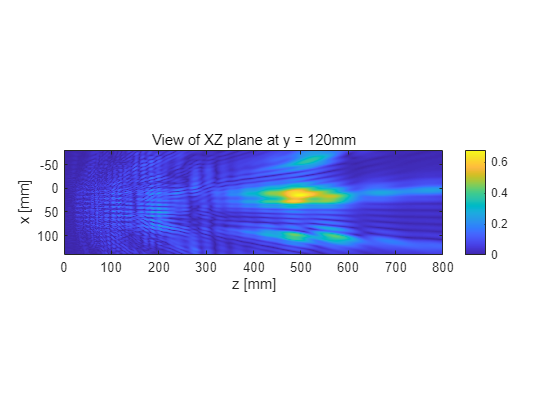


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_z.*1e3, reading_pos_x.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top');
title('View of XZ plane at y = 120mm');
colorbar;
xlabel('z [mm]');
ylabel('x [mm]');

M1 = max(Pressure_dxyz_i,[],"all")

M1 = 0.6792

XY Plane

% xy plane
[Pressure_dxyz, ~] = ...
    PFC_CalculatePressureField(...
    transducer_object, input_source,...                 % tx setting
    reading_pos_x, reading_pos_y, 0.1);

Started at 2024-07-29 23:27:59
Finished at 2024-07-29 23:31:29
Progressed time : 00:03:29


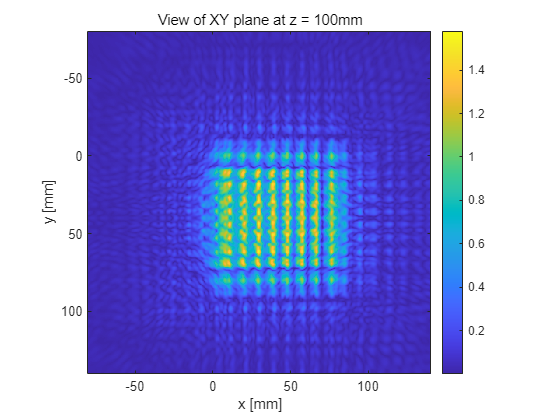


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_x.*1e3, reading_pos_y.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top');
title('View of XY plane at z = 100mm');
colorbar;
xlabel('x [mm]');
ylabel('y [mm]');

M2 = max(Pressure_dxyz_i,[],"all")

M2 = 1.5805